# Modifying Squishy Data Processing

Things we want to include:

- one matrix for all our data

- should combine with CaSO4_mixing file

- make this one big function file

Chopping off the outlier data

good_rows = 1:18000;
conductivity_list = conductivity_list(good_rows,:);
permeate_flowrate_list = permeate_flowrate_list(good_rows,:);
flowrate_list = flowrate_list(good_rows,:);
time_list = time_list(good_rows,:);
batch_flow_rate = time_list(good_rows,:);

batch_flow_rate = 	1.0e+04 *

         0
    0.0001
    0.0004
    0.0006
    0.0009
    0.0011
    0.0014
    0.0017
    0.0019
    0.0022


a/ Calculating salt rejection  = [1-(permeate conductivity)/(average conductivity on feed side of membrane)]

perm_conductivity = 0.1; % mS/c - it's ok to guess
salt_rej = (1-(perm_conductivity)/mean(conductivity_list))*100 % percentage

salt_rej = 98.0944

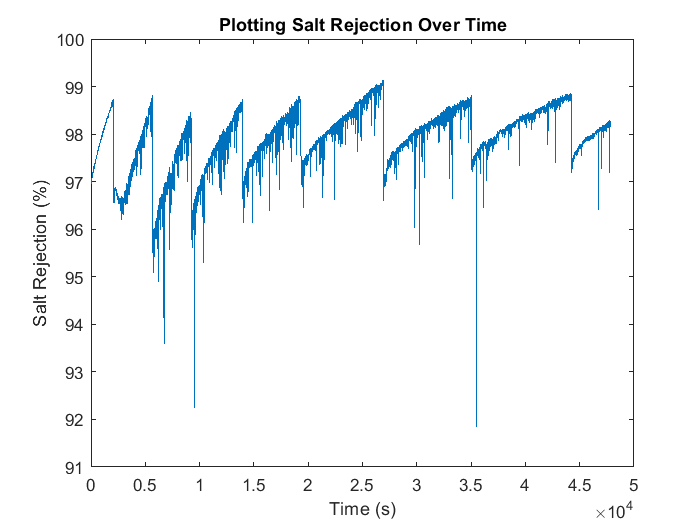

salt_rej_list = (1-(perm_conductivity)./conductivity_list)*100;

plot(time_list,salt_rej_list)
title('Plotting Salt Rejection Over Time')
xlabel('Time (s)')
ylabel('Salt Rejection (%)')

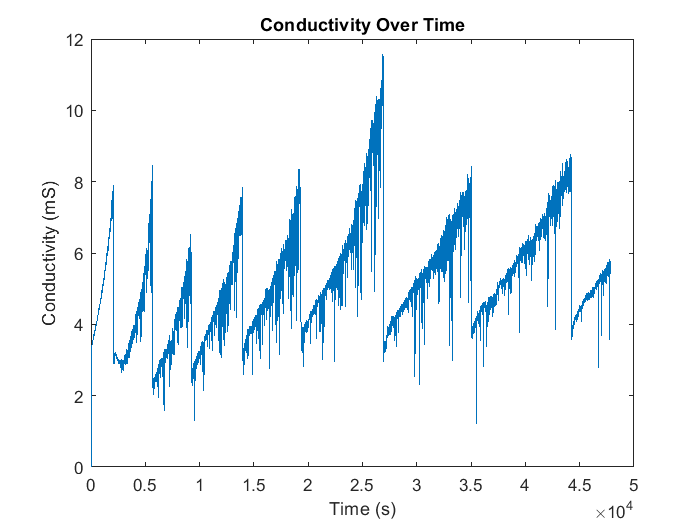


plot(time_list,conductivity_list)
title('Conductivity Over Time')
xlabel('Time (s)')
ylabel('Conductivity (mS)')

sal_mM_i = 4.6;       % mM, initial salinityfor salinity-based estimation of recovery
P_psi = 360;          % applied pressure in psi
permeate_cond = 7.8/1000;  % conductivity of permeate in mS/cm 

% preset parameters
t_min_av = 0.5;         % minutes to average over
condu_at_1mM = 0.495;   % mS/cm, conductivity of 1mM of CaSO4 and 2mM of NaCl
pi_at_1mM = 14.8729;    % psi, osmotic pressure of 1mM of CaSO4 and 2mM of NaCl
t_interval = 1;         % NOTE: data time interval is approximate
A_m = 0.0238;           % m^2, membrane area(SW measurement feed side, 2019 module)

close all
sal_mM = conductivity_list / condu_at_1mM;  % mM, salinity calculated by linear relation to conductivity
n_av = t_min_av * 60/t_interval;        % number of points to make flux avg across

sal_mM_av = movmean(sal_mM, n_av);
flowrate_av = (mass(n_av+1:end) - mass(1:end-n_av)) ./ (time(n_av+1:end) - time(1:end-n_av));

flux_lmh = flowrate_av / 1000*3600 / A_m; % L/m2.h
RR_i_cond = 1 - sal_mM_i ./ sal_mM_av; % conductivity-based instantaneous RR assuming no salt permeation!
P_bar = P_psi * 0.0689;
pi_psi = pi_at_1mM * sal_mM_av; % est. osmotic pressure in psi
pi_bar = pi_psi * 0.0689;
%perm_LMHB = flux_lmh ./ (P_bar-pi_bar(1:end-n_av)); %LMH/bar, permeability

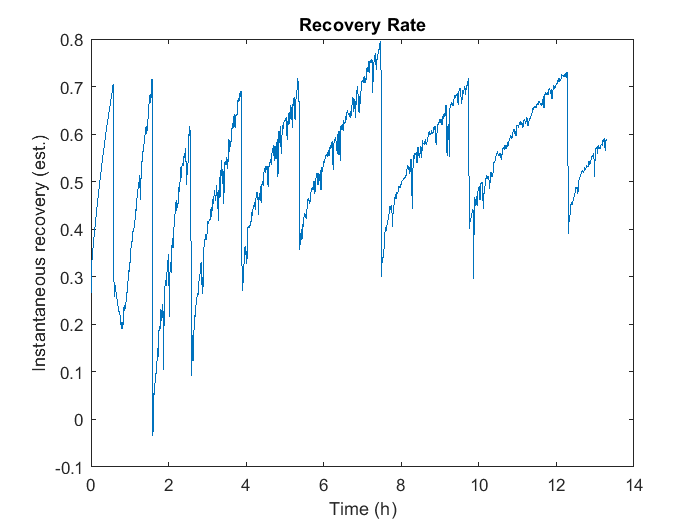

% plots recover rate
figure
plot(time_list/3600, RR_i_cond)
title("Recovery Rate")
xlabel('Time (h)')
ylabel('Instantaneous recovery (est.)')

b/ Calculate the calcium sulfate concentration at the membrane at each timestep (from input initial concentration and instantaneous recovery and including concentration polarization.)

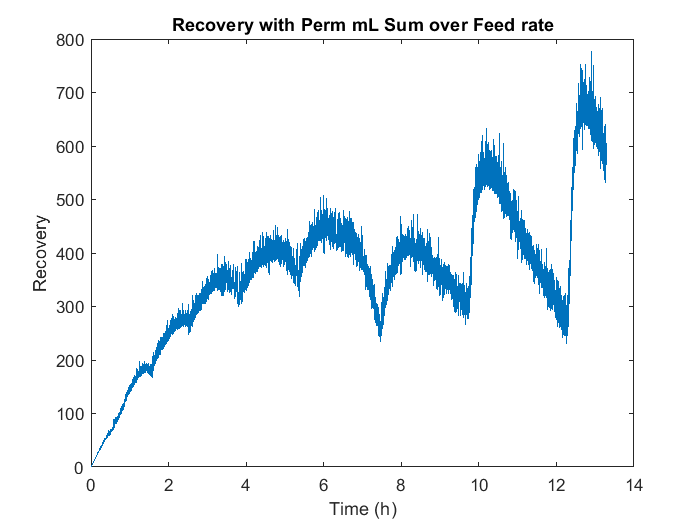

initial_conc = 626.2;    % intial concentration mg/L
mem_const = 0.99;  % membrane constant (K) 

% recovery should be going up and maybe zero at each cycle
recovery = (permeate_flowrate_list.*time_list)./(flowrate_list);  %expressed in terms of a decimal
%whats the difference between jiayuan's data based on salinity and this
%data

plot(time_list/3600, recovery)
title('Recovery with Perm mL Sum over Feed rate')
xlabel('Time (h)')
ylabel('Recovery')


pfl = permeate_flowrate_list;
Tl = time_list;

P_int = cumtrapz(Tl, pfl)

P_int = 	1.0e+05 *

         0
    0.0001
    0.0006
    0.0011
    0.0016
    0.0020
    0.0025
    0.0029
    0.0034
    0.0039


recovery_try2 = P_int ./ feed_ml

recovery_try2 =        NaN
    1.2978
    2.1455
    2.3295
    2.4822
    2.4987
    2.4107
    2.5073
    2.4643
    2.4243


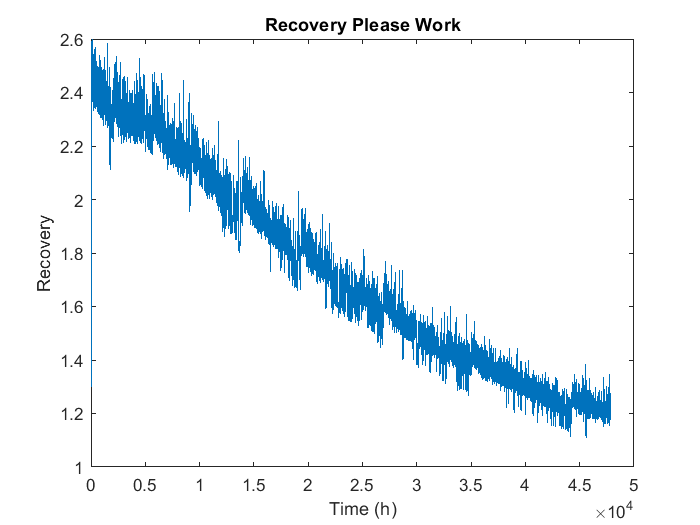

plot(time_list, recovery_try2)
title('Recovery Please Work')
xlabel('Time (h)')
ylabel('Recovery') 


time_list_min = time_list/60;
perm_ml = permeate_flowrate_list .* time_list_min;
total_perm = sum(perm_ml)

total_perm = 5.0282e+07

feed_ml = flowrate_list .* time_list_min;
total_feed = sum(feed_ml)

total_feed = 3.3635e+09

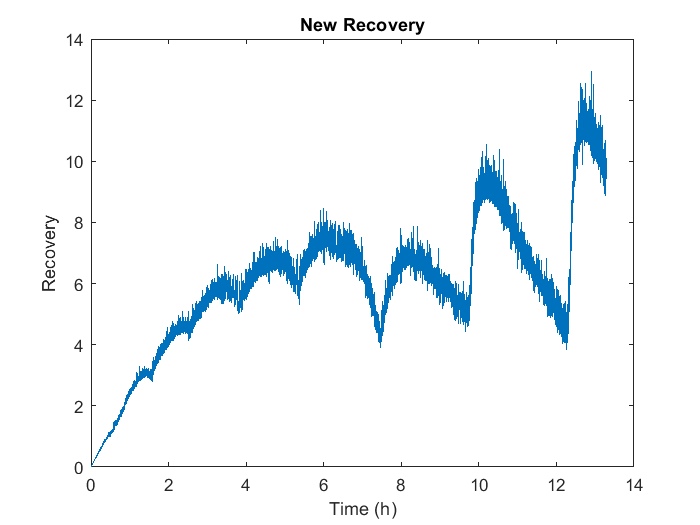


recovery_new = (perm_ml./flowrate_list); %this dont seem right

plot(time_list_min/60,recovery_new)
title('New Recovery')
xlabel('Time (h)')
ylabel('Recovery')


recovery_once = total_perm/total_feed

recovery_once = 0.0149

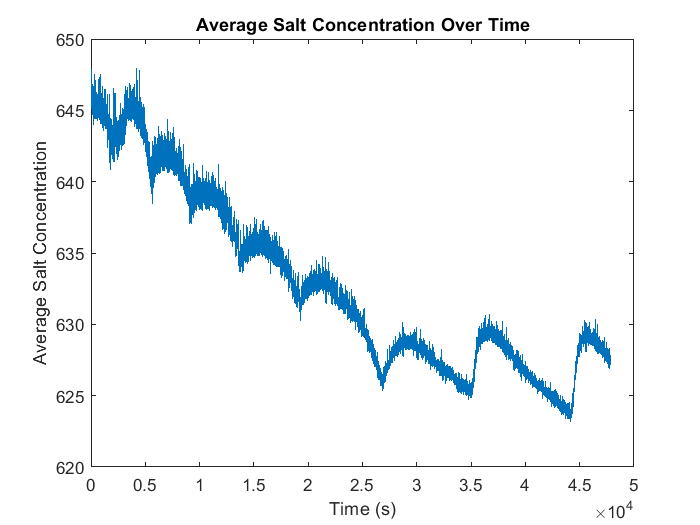


mem_CaSO4_conc = (1./(1-RR_i_cond)) .* initial_conc;          % membrane CaSO4 concentration
% what is the difference between conductivity and concentration
conc_polar = mem_const * exp(permeate_flowrate_list./mean(flowrate_list)); % concentration polarization
conc_polar_factor = mem_const * exp(permeate_flowrate_list./flowrate_list);
avg_TDS = conc_polar_factor * initial_conc; % mM/L


%plotting 
plot(time_list,avg_TDS)
title('Average Salt Concentration Over Time')
xlabel('Time (s)')
ylabel('Average Salt Concentration')

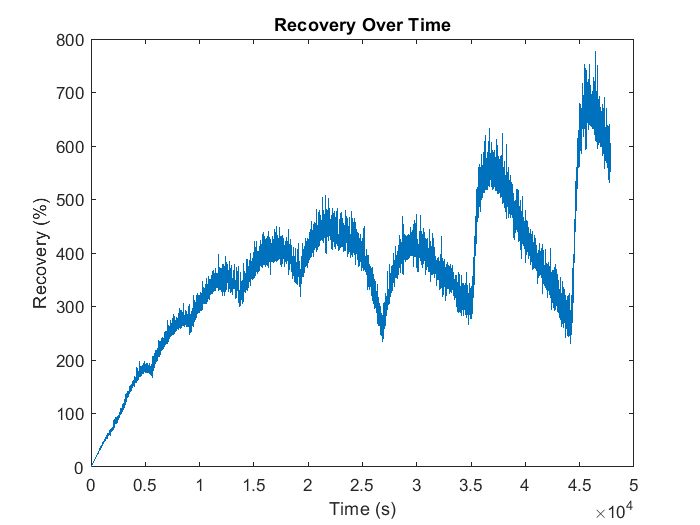


%plotting recovery
plot(time_list,recovery)
title('Recovery Over Time')
xlabel('Time (s)')
ylabel('Recovery (%)')

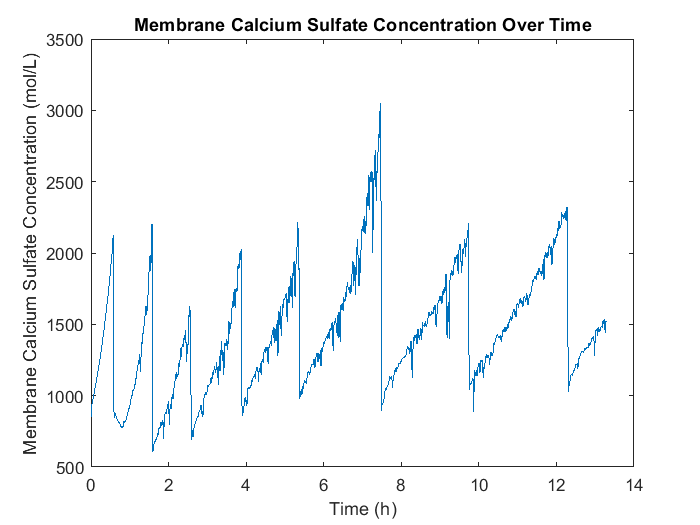


%plotting Membrane Calcium Sulfate Concentration
plot(time_list/3600,mem_CaSO4_conc)
title('Membrane Calcium Sulfate Concentration Over Time')
xlabel('Time (h)')
ylabel('Membrane Calcium Sulfate Concentration (mol/L)')

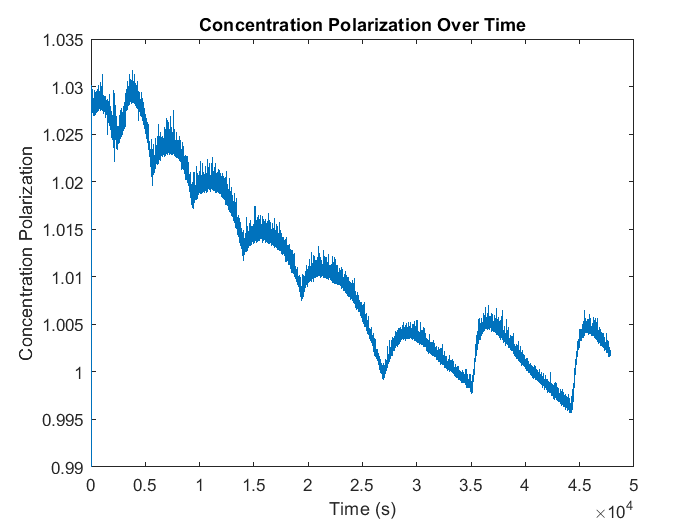


%plotting Concentration Polarization
plot(time_list,conc_polar)
title('Concentration Polarization Over Time')
xlabel('Time (s)')
ylabel('Concentration Polarization')


% plot()
% title('')
% xlabel('')
% ylabel('')

c/ Calculate the saturation index of gypsum (a.k.a. calcium sulfate dihydrate) at the membrane at each timestep.

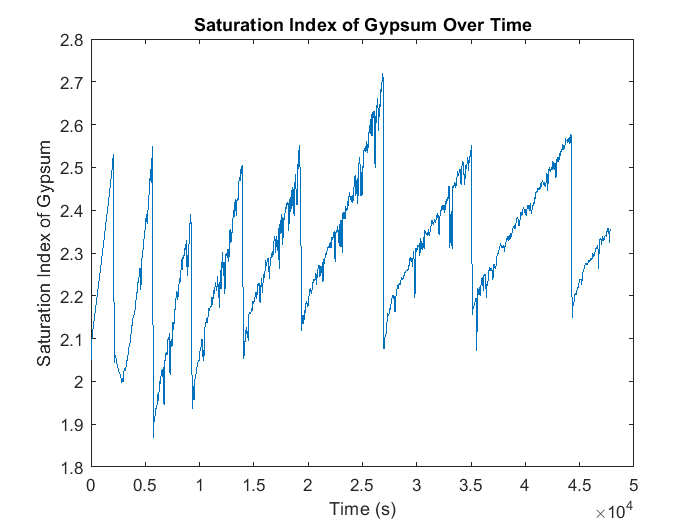

% equation in comments of doc
sat_index = 0.527 .* log(mem_CaSO4_conc) - 1.5073;

% plotting Saturation Gypsum over time
plot(time_list,sat_index)
title('Saturation Index of Gypsum Over Time')
xlabel('Time (s)')
ylabel('Saturation Index of Gypsum')

d/ Calculate the nucleation induction time of gypsum at each timestep.

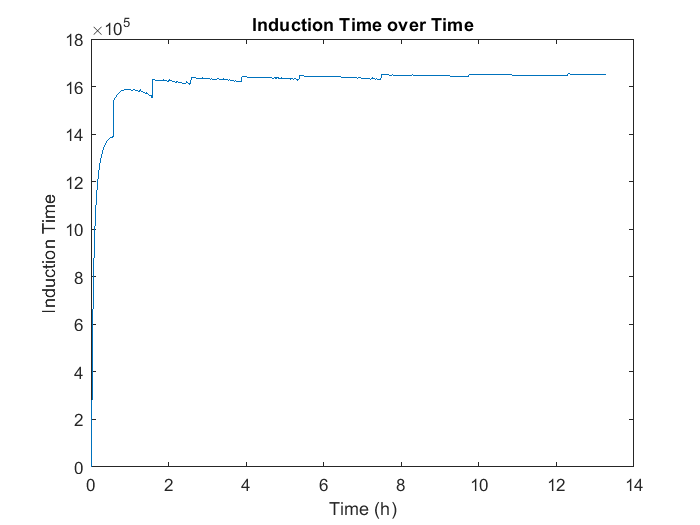

% ---------------------- hmmmmmmmmmmm need to figure out which graph is
% right
conc_over_time = mem_CaSO4_conc ./ time_list; % Membrance Concentration over Time (need to find out units)
ind_time = 1.66*(10^6).*(exp(-0.174.*conc_over_time)); % Induction Time in seconds (s)
inv_ind_time = 1./ind_time;

plot(time_list/3600,ind_time)
title('Induction Time over Time')
xlabel('Time (h)')
ylabel('Induction Time')

e/ Integrate the induction rate (i.e., the inverse of induction time) over all timesteps in each batch cycle to determine the nucleation probability per cycle

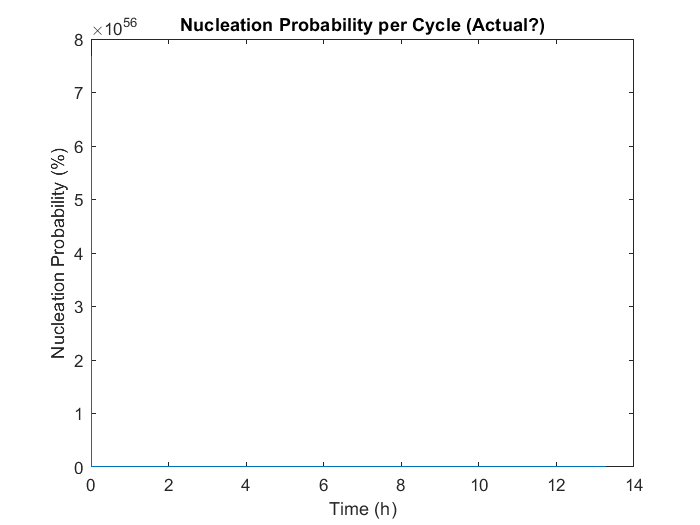

timestep = time_list(1:10:length(time_list));

nuc_prob = (log(ind_time)./conc_over_time);
nucl_prob = inv_ind_time .* time_list;

plot(time_list/3600,nucl_prob)
title('Nucleation Probability per Cycle (Actual?)')
xlabel('Time (h)')
ylabel('Nucleation Probability (%)')

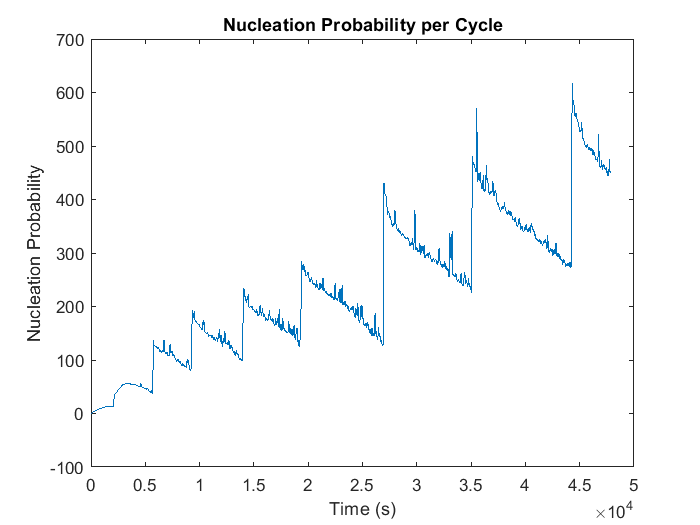


plot(time_list,nuc_prob)
title('Nucleation Probability per Cycle')
xlabel('Time (s)')
ylabel('Nucleation Probability')


% 1/induction over induction time
% rate is the probability happening in each second and do that times a time
% step and then if you add that rate * time steps it should give you the
% nucleation probability